%页码：P86
%作者；暴富
%时间：2024-07-24
%项目：example3.7 
% OPFB具有本地控制器和邻域观测器信息，实现的轨迹追踪
%控制器的构造用了本身和领导者的信息，观察器的构造用了领域的信息差，其中该信息差包括领导者状态
%该观测器严格来说，并非实际意义上的观测器，传统观测器，主要实现估计值与实际值相同
%在本协议中观测器主要用来实现估计领导者的状态，这与实际意义上的观测器原理有所差别，故不是实际意义上的观测器

clc
clear
lineStyles = linspecer(7); % 指定线型颜色,一页有几条线

%%状态初始化
m1 = 1.1;
m2 = 0.9;
k1 = 1.5;
k2 = 1;
c = 2;
A = [0,1,0,0;...
    (-k1-k2)/m1 0 k2/m1 0;...
    0 0 0 1;...
    k2/m2 0 -k2/m2 0];
B = [0;1/m1;0;0];
C = [1 0 0 0;...
    0 0 1 0];

%%拓扑结构初始化
%这里用Aij代表邻接矩阵
Aij = [0 0 0 0 0 0;...
    2 0 0 0 0 0;...
    0 6 0 0 0 0;...
    0 0 1 0 0 0;...
    0 0 0 1 0 0;...
    0 0 0 0 3 0];
L = diag(sum(Aij,2)) - Aij;
G = diag([1,0,0,0,0,0]);

%%计算控制器增益，即反馈矩阵K
%stabilizable稳定性分析，转化为可控性分析
Ro = obsv(A,C);
rank(Ro); %ans = 4结果可控
Q1 = eye(4); %想要收敛快点就增大对角值
Q2 = diag([10,10,10,10]);
%观测器的收敛速度要比控制器快，这样保证估计的状态能保持在一个相对准确的状态
R = 1;
[F,P1] = lqr(A',C',Q2,R) ;
F = F';
[K,P2] = lqr(A,-B,Q1,R) ;%%A+BK是hurwitz，故采用-B

%%仿真初始化
Ts = 0.01;
t = 0:Ts:25;
N = length(t);
%%agent初始化,7个agent，一个agent4个状态，每一页对应状态迭代
%real对应实际值，obv对应观测器
X_Real = zeros(4,6,N);
X_obv  = zeros(4,6,N);
X0_Real = zeros(4,1,N);
%x0观察者要与xi状态一致
X0_obv  = zeros(4,6,N);

%设置随机状态
%6个智能体实际值
X_Real_initial = randn(4,6);
X_Real(:,:,1) = X_Real_initial;
%6个agent观测器初始值
X_obv_initial = randn(4,6);
X_obv(:,:,1) = X_obv_initial;
%领导者的实际值
X0_Real_initial = randn(4,1);
X0_Real(:,:,1) = X0_Real_initial;
%领导者观测器，************不是实际意义上的观测器*********************
X0_obv(:,:,1) =  randn(4,6);

## **原始系统**

### **1.跟随者**

$$
\dot{x}_{i}=Ax_{i}+BK(\hat{x}_i - \hat{x}_{0i})
$$闭环系统

$$$
\dot{\hat{x}}_i=(A+BK)\hat{x}_i-cF\Bigg(\sum_{j\in N_i}a_{ij}(\tilde{y}_j-\tilde{y}_i)+g_i(y_0-C\hat{x}_{0i}-\tilde{y}_i)\Bigg)
$$$观测器

其中$$$
\tilde{y}_i=y_i-\hat{y}_i
$$
$，且$$$
\hat{y}_i = C\hat{x}_i
$$$

### 2.领导者：


$$$$
\dot{x}_0\,\,=\,\,Ax_0
$$
$$



$$$$
y_0=Cx_0
$$
$$



$$\dot{\hat{x}}_{0i}=(A+BK)\hat{x}_{0i}$$


## **离散后**

**1.跟随者**


$$x_{i}(k+1) = x_{i}(k) + T_s \Bigg(Ax_{i}(k)+BK\Bigg (\hat{x}_i(k)- \hat{x}_{0i}(k)\Bigg)\Bigg)
$$



$$$$
\hat{x}_i(k+1) = \hat{x}_i(k) + T_s\Bigg((A+BK)\hat{x}_i(k)-cF\Bigg(\sum_{j\in N_i}a_{ij}(\tilde{y}_j(k)-\tilde{y}_i(k)+g_i\Bigg(y_0(k)-C\hat{x}_{0i}(k)-\tilde{y}_i(k)\Bigg)\Bigg)
$$$$


### 2.领导者


$$$$
x_0 (k+1) = x_0(k) + Ts（Ax(k))
$$
$$



$$$$
y_0(k)=Cx_0(k)
$$
$$



$$\hat{x}_{0i}(k+1)=\hat{x}_{0i}(k)+Ts\Bigg((A+BK)\hat{x}_{0i}(k)\Bigg)$$


# 定义：


$$$$
sum\_ystate=\sum_{j\in N_i}{a_{ij}}(\tilde{y}_j(k)-\tilde{y}_i(k))=\sum_{j\in N_i}{a_{ij}}*C*\Bigg([x_j(k)-\hat{x}_j(k)]-[x_i(k)-\hat{x}_i(k)]\Bigg)
$$
$$



$$x\_state =\Bigg(x_0(k)-\hat{x}_{0i}(k)- (x_i(k)-\hat{x}_i(k))   \Bigg)$$


### 则


$$\hat{x}_i(k+1) = \hat{x}_i(k) + T_s\Bigg((A+BK)\hat{x}_i(k)-cF*\Bigg(sum\_ystate+g_i\Bigg(y_0(k)-C\hat{x}_{0i}(k)-\tilde{y}_i(k)\Bigg)\Bigg)\\=
\hat{x}_i(k) + T_s\Bigg((A+BK)\hat{x}_i(k)-cF*\Bigg(sum\_ystate+g_i\Bigg(Cx_0(k)-C\hat{x}_{0i}(k)- C(x_i(k)-\hat{x}_i(k))   \Bigg)\Bigg)\\=
\hat{x}_i(k) + T_s\Bigg((A+BK)\hat{x}_i(k)-cF*\Bigg(sum\_ystate+g_i*C*x\_state\Bigg)$$


# 整理得：

**1.跟随者**


$$x_{i}(k+1) = x_{i}(k) + T_s \Bigg(Ax_{i}(k)+cBK\Bigg (\hat{x}_i(k)- \hat{x}_{0i}(k)\Bigg)\Bigg)
$$



$$\hat{x}_i(k+1) = \hat{x}_i(k) + T_s\Bigg((A+BK)\hat{x}_i(k)-cF*\Bigg(sun\_ystate+g_i*C*x\_state\Bigg)$$


### 2.领导者


$$$$
x_0 (k+1) = x_0(k) + Ts（Ax(k))
$$
$$



$$\hat{x}_{0i}(k+1)=\hat{x}_{0i}(k)+Ts\Bigg((A+BK)\hat{x}_{0i}(k)\Bigg)$$


## 拓扑结构

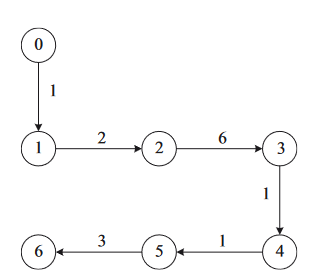

## 编程思维

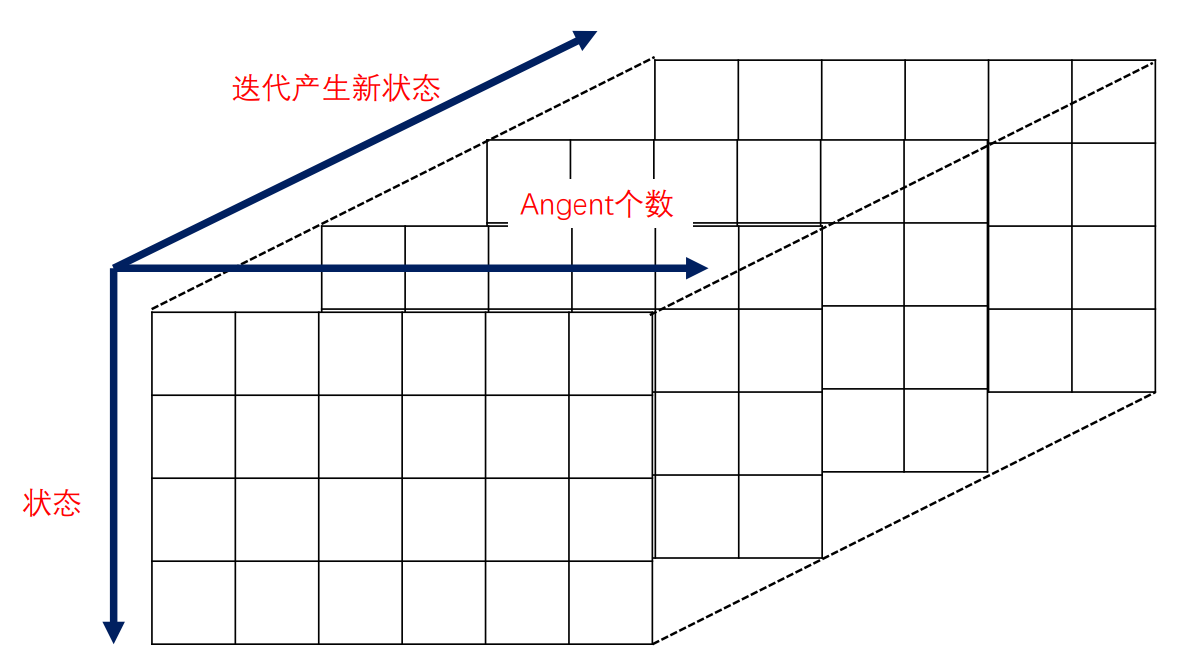

for k = 2:N
    %leader状态
    X0_Real(:,1,k) = X0_Real(:,1,k-1) + Ts*(A*X0_Real(:,1,k-1));
    for i = 1:6
        sum_ystate = 0;
        %观测器
        X0_obv(:,i,k) = X0_obv(:,i,k-1) + Ts*((A+B*K)*X0_obv(:,i,k-1));

        for j = 1:6
            
            sum_ystate = sum_ystate + Aij(i,j)*C*((X_Real(:,j,k-1)-X_obv(:,j,k-1))-(X_Real(:,i,k-1)-X_obv(:,i,k-1)));
            
        end
        
        X_Real(:,i,k) = X_Real(:,i,k-1) + Ts*(A*X_Real(:,i,k-1) + B*K*(X_obv(:,i,k-1)-X0_obv(:,i,k-1)));
        X_state = (X0_Real(:,1,k-1) - X0_obv(:,i,k-1) - (X_Real(:,i,k-1)-X_obv(:,i,k-1)));
        X_obv(:,i,k) = X_obv(:,i,k-1) + Ts*((A+B*K)*X_obv(:,i,k-1) -c*F*(sum_ystate + G(i,i)*C*X_state));
        
    end
end

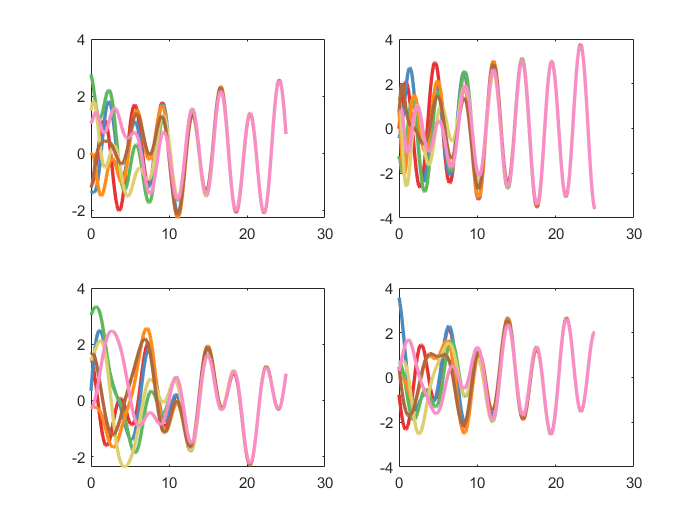

%%绘图:状态对应一直即可，x_1对x_1,x_2对x_2，x_2对x_2，x_2对x_2
%% 绘制结果
hf = figure;  %新建 图形控制句柄
hf.Color= [1 1 1]; % 控制图形的整体颜色。（scope中被默认为灰黑色，此处修改为白色）
xlim([0.0 25.0])
ylim([-3 3])

subplot(2,2,1)

plot(t,reshape(X0_Real(1,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on

%实际值
plot(t,reshape(X_Real(1,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(1,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
% %观测器值
% plot(t,reshape(X0_obv(1,1,:),1,N),'Color',lineStyles(8,:),'linestyle','-','linewidth',2);
% plot(t,reshape(X_obv(1,1,:),1,N),'Color',lineStyles(9,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,2,:),1,N),'Color',lineStyles(10,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,3,:),1,N),'Color',lineStyles(11,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,4,:),1,N),'Color',lineStyles(12,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,5,:),1,N),'Color',lineStyles(13,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(1,6,:),1,N),'Color',lineStyles(14,:),'linestyle','-','linewidth',2); 

subplot(2,2,2)

plot(t,reshape(X0_Real(2,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on

%实际值
plot(t,reshape(X_Real(2,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(2,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
% %观测器值
% plot(t,reshape(X0_obv(2,1,:),1,N),'Color',lineStyles(8,:),'linestyle','-','linewidth',2);
% plot(t,reshape(X_obv(2,1,:),1,N),'Color',lineStyles(9,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,2,:),1,N),'Color',lineStyles(10,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,3,:),1,N),'Color',lineStyles(11,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,4,:),1,N),'Color',lineStyles(12,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,5,:),1,N),'Color',lineStyles(13,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(2,6,:),1,N),'Color',lineStyles(14,:),'linestyle','-','linewidth',2); 

subplot(2,2,3)

plot(t,reshape(X0_Real(3,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on

%实际值
plot(t,reshape(X_Real(3,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(3,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 
% %观测器值
% plot(t,reshape(X0_obv(3,1,:),1,N),'Color',lineStyles(8,:),'linestyle','-','linewidth',2);
% plot(t,reshape(X_obv(3,1,:),1,N),'Color',lineStyles(9,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,2,:),1,N),'Color',lineStyles(10,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,3,:),1,N),'Color',lineStyles(11,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,4,:),1,N),'Color',lineStyles(12,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,5,:),1,N),'Color',lineStyles(13,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(3,6,:),1,N),'Color',lineStyles(14,:),'linestyle','-','linewidth',2); 

subplot(2,2,4)

plot(t,reshape(X0_Real(4,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on

%实际值
plot(t,reshape(X_Real(4,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X_Real(4,6,:),1,N),'Color',lineStyles(7,:),'linestyle','-','linewidth',2); 

% %观测器值
% plot(t,reshape(X0_obv(4,1,:),1,N),'Color',lineStyles(8,:),'linestyle','-','linewidth',2);
% plot(t,reshape(X_obv(4,1,:),1,N),'Color',lineStyles(9,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,2,:),1,N),'Color',lineStyles(10,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,3,:),1,N),'Color',lineStyles(11,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,4,:),1,N),'Color',lineStyles(12,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,5,:),1,N),'Color',lineStyles(13,:),'linestyle','-','linewidth',2); 
% plot(t,reshape(X_obv(4,6,:),1,N),'Color',lineStyles(14,:),'linestyle','-','linewidth',2); 

%%作图思路：本系统是观测器估计状态，利用估计状态，进行闭环设置，故我们只绘实际图像即可，不要绘制观测器


